***1*** a)

%%initialize
x_0 = [0 0 0 0 0]';
P_0 = diag([100,100,100,((5*pi)/180)^2,((pi)/180)^2]);

s1=[300,-100]';
s2=[300,-300]';

sigma_phi1 = pi/180;
sigma_phi2 = pi/180;
Sigma_v=0.1;
Sigma_w=pi/180;

R = diag([(sigma_phi1)^2,(sigma_phi2)^2]);
Q = diag([0,0,(Sigma_v)^2,0,(Sigma_w)^2]);




%% True track
% Sampling period
T = 0.1;
% Length of time sequence
K = 600;
% Allocate memory
omega = zeros(1,K+1);
% Turn rate
omega(150:450) = -pi/301/T;
% Initial state
x0 = [0 0 20 0 omega(1)]';
% Allocate memory
X = zeros(length(x0),K+1);
X(:,1) = x0;
% Create true track
for i=2:K+1
% Simulate
[X(:,i),~] = coordinatedTurnMotion(X(:,i-1), T);
% Set turn−rate
X(5,i) = omega(i);
end

%define two nonlinear function
f=@(x,T)coordinatedTurnMotion(x, T);
h=@(x)dualBearingMeasurement(x,s1,s2);

%getmeasurement
Y = genNonLinearMeasurementSequence(X, h, R);
X_mesure=[];
for i=1:length(Y)
[x, y] = getPosFromMeasurement(Y(1,i), Y(2,i), s1,s2);
a=[x;y];
X_mesure=[X_mesure,a];
end

sigmaPoints = @SigmaPoints;

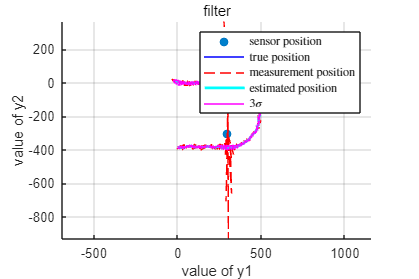


[xs, Ps, xf, Pf, xp, Pp] = nonLinRTSsmoother(Y, x_0, P_0, f, T, Q, h, R, sigmaPoints,'CKF');


%give the figures 
figure('Position',[300 300 600 400]);
scatter([300,300],[-100,-300], 'MarkerFaceColor', [0 0.5 0.8]);
hold on
plot(X(1,:),X(2,:),'b');
plot(X_mesure(1,:),X_mesure(2,:),'r--');
plot(xf(1,:),xf(2,:),'cyan','Linewidth',2);
% get 3sigma ellipse
for j=1:5:size(xf,2)
     [sf] = sigmaEllipse2D (xf(1:2,j),Pf(1:2,1:2,j),3, 600);
     plot(sf(1,:),sf(2,:),'m');
end
grid on
axis equal
hold off
xlabel('value of y1') % Set x-axis label
ylabel('value of y2') % Set y-axis label
legend('sensor position','true position','measurement position','estimated position','$3\sigma$','interpreter','latex')
title('filter')

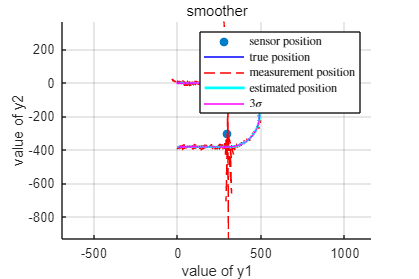


%give the figures 
figure('Position',[300 300 600 400]);
scatter([300,300],[-100,-300], 'MarkerFaceColor', [0 0.5 0.8]);
hold on
plot(X(1,:),X(2,:),'b');
plot(X_mesure(1,:),X_mesure(2,:),'r--');
plot(xs(1,:),xs(2,:),'cyan','Linewidth',2);
% get 3sigma ellipse
for j=1:5:size(xs,2)
     [ss] = sigmaEllipse2D (xs(1:2,j),Ps(1:2,1:2,j),3, 600);
     plot(ss(1,:),ss(2,:),'m');
end
grid on
axis equal
hold off
xlabel('value of y1') % Set x-axis label
ylabel('value of y2') % Set y-axis label
legend('sensor position','true position','measurement position','estimated position','$3\sigma$','interpreter','latex')
title('smoother')

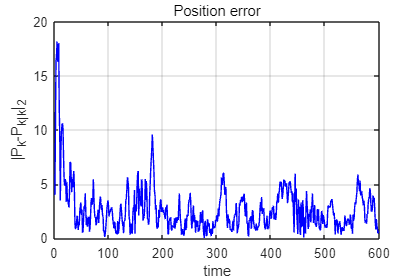


Nf = vecnorm(X(1:2,2:end)-xf(1:2,:));
nf=1:1:length(xf);

figure('Position',[300 300 600 400]);
plot(nf,Nf,'b');
grid on
xlabel('time') % Set x-axis label
ylabel('|P_k-P_{k|k}|_2') % Set y-axis label
title('Position error')

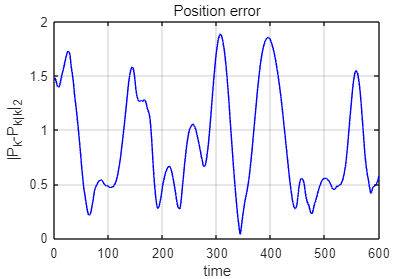




Ns = vecnorm(X(1:2,2:end)-xs(1:2,:));
ns=1:1:length(xf);

figure('Position',[300 300 600 400]);
plot(ns,Ns,'b');
grid on
xlabel('time') % Set x-axis label
ylabel('|P_k-P_{k|k}|_2') % Set y-axis label
title('Position error')

1 b)

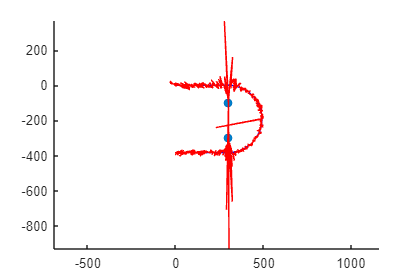


Y_b=Y;
v=2;
Y_b(:,300)=Y(:,300)+(mvnrnd([0;0],diag([v,v]))');

X_mesureb=[];
for i=1:length(Y)
[xb, yb] = getPosFromMeasurement(Y_b(1,i), Y_b(2,i), s1,s2);
a=[xb;yb];
X_mesureb=[X_mesureb,a];
end


figure('Position',[300 300 600 400]);
scatter([300,300],[-100,-300], 'MarkerFaceColor', [0 0.5 0.8]);
hold on
plot(X(1,:),X(2,:),'b');
plot(X_mesureb(1,:),X_mesureb(2,:),'r');
axis equal
hold off

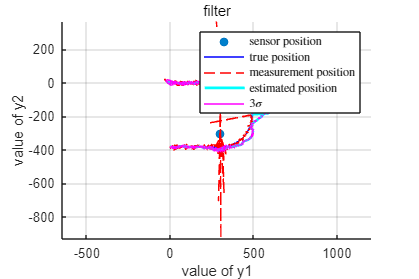


[xs, Ps, xf, Pf, xp, Pp] = nonLinRTSsmoother(Y_b, x_0, P_0, f, T, Q, h, R, sigmaPoints,'CKF');


%give the figures 
figure('Position',[300 300 600 400]);
scatter([300,300],[-100,-300], 'MarkerFaceColor', [0 0.5 0.8]);
hold on
plot(X(1,:),X(2,:),'b');
plot(X_mesureb(1,:),X_mesureb(2,:),'r--');
plot(xf(1,:),xf(2,:),'cyan','Linewidth',2);
% get 3sigma ellipse
for j=1:5:size(xf,2)
     [sf] = sigmaEllipse2D (xf(1:2,j),Pf(1:2,1:2,j),3, 600);
     plot(sf(1,:),sf(2,:),'m');
end
grid on
axis equal
hold off
xlabel('value of y1') % Set x-axis label
ylabel('value of y2') % Set y-axis label
legend('sensor position','true position','measurement position','estimated position','$3\sigma$','interpreter','latex')
title('filter')

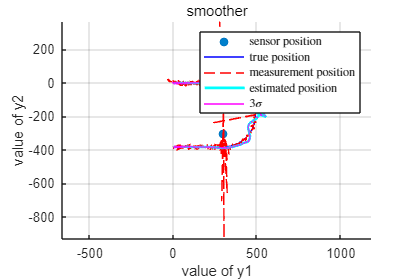


%give the figures 
figure('Position',[300 300 600 400]);
scatter([300,300],[-100,-300], 'MarkerFaceColor', [0 0.5 0.8]);
hold on
plot(X(1,:),X(2,:),'b');
plot(X_mesureb(1,:),X_mesureb(2,:),'r--');
plot(xs(1,:),xs(2,:),'cyan','Linewidth',2);
% get 3sigma ellipse
for j=1:5:size(xs,2)
     [ss] = sigmaEllipse2D (xs(1:2,j),Ps(1:2,1:2,j),3, 600);
     plot(ss(1,:),ss(2,:),'m');
end
grid on
axis equal
hold off
xlabel('value of y1') % Set x-axis label
ylabel('value of y2') % Set y-axis label
legend('sensor position','true position','measurement position','estimated position','$3\sigma$','interpreter','latex')
title('smoother')

***2*** a)


%set the parameters 
x_0=2;
P_0=8;
Q=1.5;
R=3;
A=1;
H=1;
N=30;
%use functions to get sequences
X_s=genLinearStateSequence(x_0, P_0, A, Q, N);
Y_s=genLinearMeasurementSequence(X_s,H,R);


%KF
[X_est, P_e,~,~,~] = kalmanFilter(Y_s,x_0, P_0, A, Q, H, R);

%change the sigma^2 P_e into a two dimension array so we cancalculate later
P_est =[];
for i =1:length(X_est)
    P_est =[P_est P_e(:,:,i)];
end


%PF
proc_f=@(x)(A*x);
meas_h=@(x)(H*x);

Np=100;

[xfp, Pp, Xp, Wp] = pfFilter(x_0, P_0,Y_s,proc_f,Q,meas_h, R,Np,0,[]);
%change the sigma^2 P_e into a two dimension array so we cancalculate later
Pfp =[];
for i =1:length(xfp)
    Pfp =[Pfp Pp(:,:,i)];
end
[xfpr, Ppr, Xpr, Wpr] = pfFilter(x_0, P_0,Y_s,proc_f,Q,meas_h, R,Np,1,[]);
%change the sigma^2 P_e into a two dimension array so we cancalculate later
Pfpr =[];
for i =1:length(xfpr)
    Pfpr =[Pfpr Ppr(:,:,i)];
end

.

%%compute MSE
%MSE for KF
MSEK=immse(X_s(2:end),X_est)

MSEK = 1.7058

%MSE for PF with R
MSEPTR=immse(X_s(2:end),xfpr)

MSEPTR = 1.9300

%MSE for PF
MSEP=immse(X_s(2:end),xfp)

MSEP = 7.3827

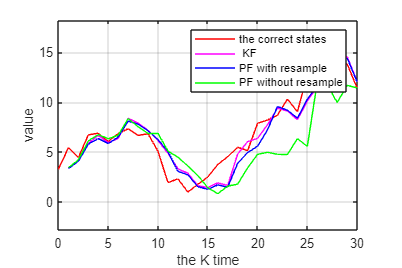

%%figures
figure('Position',[300 300 600 400]);
plot(0:30, X_s, 'r');
hold on
axis equal
plot(1:30, Y_s, 'k--o');
plot(1:30,X_est,'m');
plot(1:30,xfpr,'b');
plot(1:30,xfp,'g');
hold off
grid on 
xlabel('the K time')
ylabel('value')  
legend('the correct states','measurement',' KF','PF with resample','PF without resample')

.

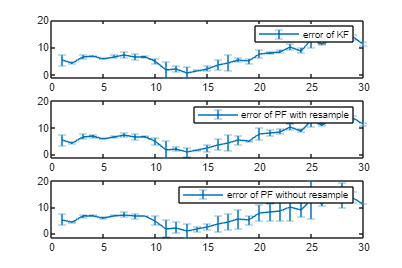

%%errorbar
a=1:30;
figure('Position',[300 300 600 400]);
hold on 
grid on 
subplot(3,1,1)
errorbar(a,X_s(2:end),X_s(2:end)-X_est) 
legend('error of KF')
subplot(3,1,2)
errorbar(a,X_s(2:end),X_s(2:end)-xfpr)
legend('error of PF with resample')
subplot(3,1,3)
errorbar(a,X_s(2:end),X_s(2:end)-xfp) 
legend('error of PF without resample')

.

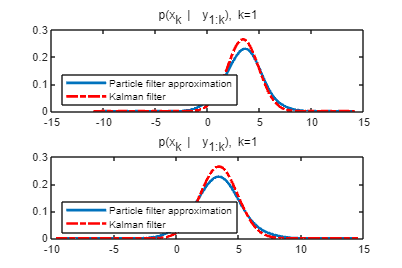

sigma=1;
k1=1;
k2=15;
k3=30;
figure('Position',[300 300 600 400]); 
grid on 
subplot(2,1,1)
plotPostPdf(k1, Xp(:,:,k1),  (Wp(:,k1))',X_est, P_e, 0, sigma, []);
subplot(2,1,2)
plotPostPdf(k1, Xpr(:,:,k1),  (Wpr(:,k1))',X_est, P_e, 0, sigma, []);

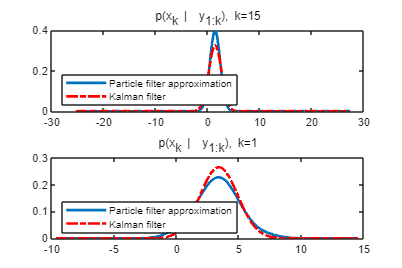


figure('Position',[300 300 600 400]); 
grid on 
subplot(2,1,1)
plotPostPdf(k2, Xp(:,:,k2), (Wp(:,k2))', X_est, P_e, 0, sigma, []);
subplot(2,1,2)
plotPostPdf(k1, Xpr(:,:,k1),  (Wpr(:,k1))',X_est, P_e, 0, sigma, []);

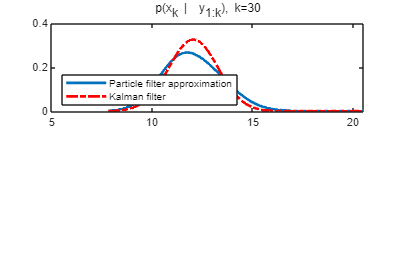


figure('Position',[300 300 600 400]); 
grid on 
subplot(2,1,1)
plotPostPdf(k3, Xp(:,:,k3), (Wp(:,k3))', X_est, P_e,0, sigma, []);
subplot(2,1,1)
plotPostPdf(k3, Xpr(:,:,k3), (Wpr(:,k3))', X_est, P_e,0, sigma, []);

2 b)

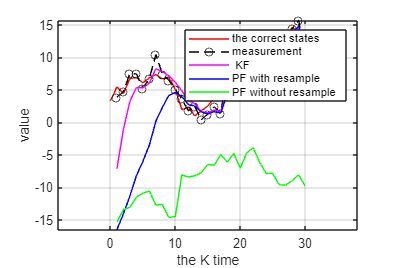


x_b=-20;
P_b=2;

%KF
[x_Kb, P_Kb,~,~,~] = kalmanFilter(Y_s,x_b, P_b, A, Q, H, R);
%PF with resample
[x_Prb, P_Prb, X_Prb, W_Prb] = pfFilter(x_b, P_b,Y_s,proc_f,Q,meas_h, R,Np,1,[]);
%PF without resample
[x_Pb, P_Pb, X_Pb, W_Pb] = pfFilter(x_b, P_b,Y_s,proc_f,Q,meas_h, R,Np,0,[]);

%%figures
figure('Position',[300 300 600 400]);
plot(0:30, X_s, 'r');
hold on
axis equal
plot(1:30, Y_s, 'k--o');
plot(1:30,x_Kb,'m');
plot(1:30,x_Prb,'b');
plot(1:30,x_Pb,'g');
hold off
grid on 
xlabel('the K time')
ylabel('value')  
legend('the correct states','measurement',' KF','PF with resample','PF without resample')

2 c)

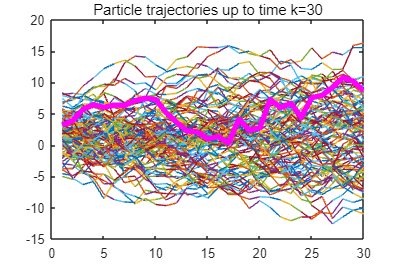

plotFunc=@(k,Xk,Xkmin1,j)plotPartTrajs(k, Xk, Xkmin1, 1, j);
figure('Position',[300 300 600 400]);
[xfp, Pp, Xp, Wp] = pfFilter(x_0, P_0,Y_s,proc_f,Q,meas_h, R, Np,0,plotFunc);hold on
plot(0:30, X_s, 'r',LineWidth=2);
plot(1:30,xfp,'m',LineWidth=4);
hold off

2 d)

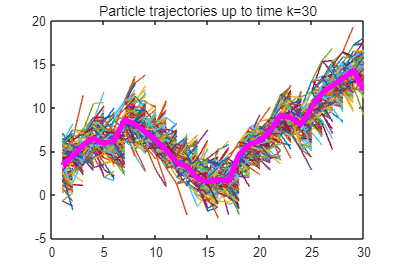

plotFunc=@(k,Xk,Xkmin1,j)plotPartTrajs(k, Xk, Xkmin1, 1, j);
figure('Position',[300 300 600 400]);
[xfpr, Ppr, Xpr, Wrp] = pfFilter(x_0, P_0,Y_s,proc_f,Q,meas_h, R, Np,1,plotFunc);hold on
plot(0:30, X_s, 'r',LineWidth=2);
plot(1:30,xfpr,'m',LineWidth=4);
hold off

#### 3 a)b)

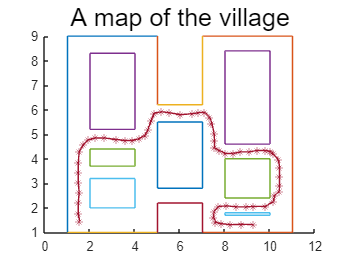

load("Xk.mat");
sigma_r=0.05;

%get v from the Xk
n=length(Xk);
v_measure=zeros(2,n-1);
for i= 1:(n-1)
v_measure(:,i)=Xk(:,(i+1))-Xk(:,i)+(mvnrnd(zeros(2,1),(sigma_r)^2*eye(2,2)))';
end

#### 3 d)

T=1;
%CV model
%initialize
x_0=[1.537;1.456;-0.088;0.305];
P_0=zeros(length(x_0));

A=diag([1,1,1,1]);
A(1,3)=T;
A(2,4)=T;
H=[0,0,1,0;0,0,0,1];
%set handle for modelfunction
proc_fcv=@(x)(A*x);
meas_hv=@(x)(H*x);

%noise tuning
sigma_q=5;
sigma_r=0.05;
Q=diag([0,0,sigma_q^2,sigma_q^2]);
R=(sigma_r)^2*eye(2,2);


%PF without map  (_c)
N=10000;
[x_c, P_c, X_pc, W_pc] = pfFilter(x_0, P_0, v_measure, proc_fcv, Q, meas_hv, R, N, 1, []);


%PF with map (_cv)
N=10000;
[x_cv, P_cv, X_pcv, W_pcv] = pfFiltermap(x_0, P_0, v_measure, proc_fcv, Q, meas_hv, R, N, 1, []);

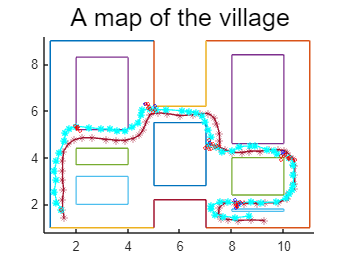

showtrajectory(Xk,x_c,X_pc,W_pc,1);

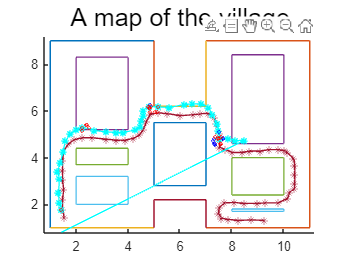

showtrajectory(Xk,x_cv,X_pcv,W_pcv,1);

#### 3 e)

# plotPartTrajs

function plotPartTrajs(k, Xk, Xkmin1, ~, j)
%PLOTPARTTRAJS Summary of this function goes here
%   Plots lines between ith sample of Xk and j(i)th sample of Xk-1. When 
%   repeated during a particle filter execution, this will produce particle 
%   trajectories illustration over time.
%
%   This function is intended to be passed as a function handle into your
%   particle filter function.
%
% Inputs:
%   k           time instance index
%   Xk          [n x N] N particles of dimension n to approximate p(x_k).
%   Xkmin1      [n x N] N particles of dimension n to approximate p(x_k-1).
%   Wk          [1 x N] Corresponding weights.
%   j           Index vector such that Xk(:,i) = Xkmin1(:,j(i))

    if (size(Xk,2) <= 100) % At most 50 particles may be plotted
        for i = 1:size(Xk,2) % loop through all particles
            plot([k-1 k], [Xkmin1(1,j(i)) Xk(1,i)],'color',[0.8,0.8,0.8]);
            hold on 
        end
        title(['Particle trajectories up to time k=', num2str(k)]);
        pause(0.05);
    else
        disp('Too many particles to plot!'); 
    end
end     

# plotPostPdf

function plotPostPdf(k, Xk, Wk, xf, Pf, bResample, sigma, ax)
%PLOTPOSTPDF Plots blurred pdf for a PF posterior, and plots a Kalman
% posterior to compare with.
%
%   This function is intended to be used as a function handle for a
%   compatible particle filter function. It is meant to be called each time
%   the particle filter has updated the particles (but before any
%   resampling has been carried out.)
%
%   To use it in your filter you should first compute xf, Pf, and set
%   bResample, sigma and ax.
%   Then define a function handle
%       plotFunc_handle  = @(k, Xk, Xkmin1, Wk, j) ...
%                          (plotPostPdf(k, Xk, Wk, xf, Pf, bResample, sigma, ax))
%   Then call your PF-function with plotFunc_handle as plotFunc argument.
%
% Inputs:
%   k           time instance index
%   Xk          [n x N] N particles of dimension n to approximate p(x_k).
%   Wk          [1 x N] Corresponding weights.
%   xf          [n x K] Filter posteriors for some filter to compare with
%   Pf          [n x n x K] Filter posterior covariances for ^
%   bResample   Flag for resampling. False: do not resample, True: resample
%   sigma       Controls the kernel width for blurring particles.
%   ax          [xmin xmax ymin ymax] Used for setting the x-axis limits to
%               a value that doesn't change through iterations of the PF
%               filter.

    N = size(Xk,2);

    % Let us first determine the x-interval of interest:
    xmin =    min(Xk(1,:)); %ax(1);
    xmax =    max(Xk(1,:)); %ax(2); 
    X    =    linspace(xmin-(xmax-xmin)/3, xmax+(xmax-xmin)/3, 800);

    % We can now construct a continuous approximation to the posterior
    % density by placing a Gaussian kernel around each particle
    pApprox = zeros(size(X));   % A vector that will contain the pdf values

    if bResample
        sigma=(xmax-xmin)/sqrt(N);
    end
    
    for i = 1 : N
        pApprox = pApprox + Wk(1,i)*normpdf(Xk(1,i), X, sigma);
    end

    % We are now ready to plot the densities
    
    % figure;
    set(gcf, 'Name', ['p_',num2str(k), '_', 'SIR']);
    % clf
    
    plot(X, pApprox, 'LineWidth', 2)   % This is the PF approximation
    hold on
    plot(X, normpdf(xf(1,k), X, sqrt(Pf(1,1,k))), 'r-.', 'LineWidth', 2) % KF posterior density
    legend('Particle filter approximation', 'Kalman filter', 'Location', 'southwest')
    title(['p(x_k |  y_{1:k}), k=', num2str(k)])
    hold off;
    % pause()
end

# generate linear and linear KF

function X = genLinearStateSequence(x_0, P_0, A, Q, N)
%GENLINEARSTATESEQUENCE generates an N-long sequence of states using a 
%    Gaussian prior and a linear Gaussian process model
%
%Input:
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   N           [1 x 1] Number of states to generate
%
%Output:
%   X           [n x N+1] State vector sequence
mu=(mvnrnd(x_0,P_0))';

X=[mu];
for i= 1:N
    mu=A*mu+(mvnrnd(zeros(length(Q),1),Q))';
    X=[X mu];
    
end
end


function Y = genLinearMeasurementSequence(X, H, R)
%GENLINEARMEASUREMENTSEQUENCE generates a sequence of observations of the state 
% sequence X using a linear measurement model. Measurement noise is assumed to be 
% zero mean and Gaussian.
%
%Input:
%   X           [n x N+1] State vector sequence. The k:th state vector is X(:,k+1)
%   H           [m x n] Measurement matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   Y           [m x N] Measurement sequence
%

% your code here
Y=[];
for i=2:length(X)
    y=H*X(:,i)+(mvnrnd(zeros(length(R),1),R))';
    Y=[Y y];
end
end

function [X, P,X_p, P_p,V] = kalmanFilter(Y_data, x_0, P_0, A, Q, H, R)
%KALMANFILTER Filters measurements sequence Y using a Kalm0an filter. 
%
%Input:
%   Y           [m x N] Measurement sequence
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   x           [n x N] Estimated state vector sequence
%   P           [n x n x N] Filter error convariance
%
%% process Y_data

Y=[];
for i=1:length(Y_data)
   if ~isnan(Y_data(:,i)) 
     Y=[Y,Y_data(:,i)];
   end
end

%% Parameters
N = size(Y,2);

n = length(x_0);
m = size(Y,1);

%% Data allocation
X = zeros(n,N);
P = zeros(n,n,N);
V = zeros(m,N);


X_p = zeros(n,N);
P_p = zeros(n,n,N);

x_up=x_0;
P_up=P_0;

for i=1:N
[x_pre, P_pre] = linearPrediction(x_up, P_up, A, Q);
[x_up, P_up, v_up] = linearUpdate(x_pre, P_pre, Y(:,i), H, R);


X_p(:,i)=x_pre;
P_p(:,:,i)=P_pre;

X(:,i)=x_up;
V(:,i)=v_up;
P(:,:,i)=P_up;
end

end


function [x, P] = linearPrediction(x, P, A, Q)
x=A*x;
P=A*P*A'+Q;
end
function [x, P, v] = linearUpdate(x, P, y, H, R)
v=y-H*x;
s=H*P*H'+R;
k=P*H'*inv(s);

x=x+k*v;
P=P-k*s*k';
end

# sigmaEllipse2D

function [ xy ] = sigmaEllipse2D( mu, Sigma, level, nPoints )
%SIGMAELLIPSE2D generates x,y-points which lie on the ellipse describing
% a sigma level in the Gaussian density defined by mean and covariance.
%
%Input:
% MU [2 x 1] Mean of the Gaussian density
% SIGMA [2 x 2] Covariance matrix of the Gaussian density
% LEVEL Which sigma level curve to plot. Default = 3.
% NPOINTS Number of points on the ellipse to generate. Default = 32.
%
%Output:
% XY 2 x npoints matrix. First row holds x-coordinates, second
% row holds the y-coordinates.

if nargin < 3
level = 3;
end
if nargin < 4
nPoints = 32;
end

th = linspace(0,2*pi,nPoints);
xy = mu + level*sqrtm(Sigma)*[cos(th); sin(th)];

end


# getPosFromMeasurement

function [x, y] = getPosFromMeasurement(y1, y2, s1, s2)
%GETPOSFROMMEASUREMENT computes the intersection point
%(transformed 2D measurement in Cartesian coordinate
%system) given two sensor locations and two bearing
%measurements, one from each sensor.
%INPUT: y1: bearing measurement from sensor 1
% y2: bearing measurement from sensor 2
% s1: location of sensor 1 in 2D Cartesian
% s2: location of sensor 2 in 2D Cartesian
%OUTPUT: x: coordinate of intersection point on x axis
% y: coordinate of intersection point on y axis
%This problem can be formulated as solving a set of two
%linear equations with two unknowns. Specifically, one
%would like to obtain (x,y) by solving
%(y−s1(2))=(x−s1(1))tan(y1) and (y−s2(2))=(x−s2(1))tan(y2).
x = (s2(2)-s1(2)+tan(y1)*s1(1)-tan(y2)*s2(1))/(tan(y1)-tan(y2));
y = s1(2)+tan(y1)*(x-s1(1));
end

# genNonLinearMeasurementSequence

function Y = genNonLinearMeasurementSequence(X, h, R)
%GENNONLINEARMEASUREMENTSEQUENCE generates ovservations of the states 
% sequence X using a non-linear measurement model.
%
%Input:
%   X           [n x N+1] State vector sequence
%   h           Measurement model function handle
%   h           Measurement model function handle
%               [hx,Hx]=h(x) 
%               Takes as input x (state) 
%               Returns hx and Hx, measurement model and Jacobian evaluated at x
%   R           [m x m] Measurement noise covariance
%
%Output:
%   Y           [m x N] Measurement sequence
%

% Your code here
Y=[];
for i=2:length(X)
    [hx,~]=h(X(:,i));
    y=hx+(mvnrnd(zeros(length(R),1),R))';
    Y=[Y y];
end
end

# motion model and measurement model

function [fx, Fx] = coordinatedTurnMotion(x, T)
%COORDINATEDTURNMOTION calculates the predicted state using a coordinated
%turn motion model, and also calculated the motion model Jacobian
%
%Input:
%   x           [5 x 1] state vector
%   T           [1 x 1] Sampling time
%
%Output:
%   fx          [5 x 1] motion model evaluated at state x
%   Fx          [5 x 5] motion model Jacobian evaluated at state x
%
% NOTE: the motion model assumes that the state vector x consist of the
% following states:
%   px          X-position
%   py          Y-position
%   v           velocity
%   phi         heading
%   omega       turn-rate

% Your code for the motion model here
% fx = ...

%Check if the Jacobian is requested by the calling function
if nargout > 1
    % Your code for the motion model Jacobian here
    % Fx = ...
    
    fx=[x(1)+T*x(3)*cos(x(4));x(2)+T*x(3)*sin(x(4));x(3);x(4)+T*x(5);x(5)];
    
    Fx=[1,0,T*cos(x(4)),T*x(3)*(-sin(x(4))),0;
        0,1,T*sin(x(4)),T*x(3)*cos(x(4)),0;
        0,0,1,0,0;
        0,0,0,1,T;
        0,0,0,0,1];
end
end
function [hx, Hx] = dualBearingMeasurement(x, s1, s2)
%DUOBEARINGMEASUREMENT calculates the bearings from two sensors, located in 
%s1 and s2, to the position given by the state vector x. Also returns the
%Jacobian of the model at x.
%
%Input:
%   x           [n x 1] State vector, the two first element are 2D position
%   s1          [2 x 1] Sensor position (2D) for sensor 1
%   s2          [2 x 1] Sensor position (2D) for sensor 2
%
%Output:
%   hx          [2 x 1] measurement vector
%   Hx          [2 x n] measurement model Jacobian
%
% NOTE: the measurement model assumes that in the state vector x, the first
% two states are X-position and Y-position.

% Your code here

hx=[atan2(x(2)-s1(2),x(1)-s1(1));
    atan2(x(2)-s2(2),x(1)-s2(1))];

a=zeros(1,size(x,1)-2);

Hx=[-(x(2)-s1(2))/((x(1)-s1(1))^2+(x(2)-s1(2))^2)   ,   (x(1)-s1(1))/((x(1)-s1(1))^2+(x(2)-s1(2))^2)   ,a;
    -(x(2)-s2(2))/((x(1)-s2(1))^2+(x(2)-s2(2))^2)   ,   (x(1)-s2(1))/((x(1)-s2(1))^2+(x(2)-s2(2))^2)   ,a];

end

# Smoother

function [xs, Ps, xf, Pf, xp, Pp] = nonLinRTSsmoother(Y, x_0, P_0, f, T, Q, h, R, sigmaPoints, type)
%NONLINRTSSMOOTHER Filters measurement sequence Y using a 
% non-linear Kalman filter. 
%
%Input:
%   Y           [m x N] Measurement sequence for times 1,...,N
%   x_0         [n x 1] Prior mean for time 0
%   P_0         [n x n] Prior covariance
%   f                   Motion model function handle
%   T                   Sampling time
%   Q           [n x n] Process noise covariance
%   S           [n x N] Sensor position vector sequence
%   h                   Measurement model function handle
%   R           [n x n] Measurement noise covariance
%   sigmaPoints Handle to function that generates sigma points.
%   type        String that specifies type of non-linear filter/smoother
%
%Output:
%   xf          [n x N]     Filtered estimates for times 1,...,N
%   Pf          [n x n x N] Filter error convariance
%   xp          [n x N]     Predicted estimates for times 1,...,N
%   Pp          [n x n x N] Filter error convariance
%   xs          [n x N]     Smoothed estimates for times 1,...,N
%   Ps          [n x n x N] Smoothing error convariance

% your code here!
% We have offered you functions that do the non-linear Kalman prediction and update steps.
% Call the functions using
% [xPred, PPred] = nonLinKFprediction(x_0, P_0, f, T, Q, sigmaPoints, type);
% [xf, Pf] = nonLinKFupdate(xPred, PPred, Y, S, h, R, sigmaPoints, type);
% Call the functions using
n=length(x_0);
N=size(Y,2);

xf=zeros(n,N);
Pf=zeros(n,n,N);
xp=zeros(n,N);
Pp=zeros(n,n,N);

x_up=x_0;
P_up=P_0;
for i=1:N 
[x_pre, P_pre] = nonLinKFprediction(x_up, P_up, f, T, Q, sigmaPoints, type);
[x_up, P_up] = nonLinKFupdate(x_pre, P_pre, Y(:,i), h, R, sigmaPoints, type);
 xf(:,i)=x_up;
 Pf(:,:,i)=P_up;
 xp(:,i)=x_pre;
 Pp(:,:,i)=P_pre;
end

xs=zeros(n,N);
Ps=zeros(n,n,N);


xs(:,N)= xf(:,N);
Ps(:,:,N)=Pf(:,:,N);
for j=N:-1:2
[x_s, P_s] = nonLinRTSSupdate(xs(:,j), Ps(:,:,j), xf(:,j-1), Pf(:,:,j-1), xp(:,j), Pp(:,:,j),f, T, sigmaPoints, type);
xs(:,j-1)=x_s;
Ps(:,:,j-1)=P_s;
end
end

function [xs, Ps] = nonLinRTSSupdate(xs_kplus1, Ps_kplus1, xf_k, Pf_k, xp_kplus1, Pp_kplus1, ...
                                     f, T, sigmaPoints, type)
    % Your code here! Copy from previous task!
     switch type
        case 'EKF'
            % Your EKF update here
            [fx,Fx]=f(xf_k,T);
            
            G=Pf_k*Fx'*inv(Pp_kplus1);
            xs=xf_k+G*(xs_kplus1-fx);
            Ps=Pf_k-G*(Pp_kplus1-Ps_kplus1)*G';
        case 'UKF'
            % Your UKF update here
           [X,W] = sigmaPoints(xf_k, Pf_k, 'UKF');
           P=zeros(length(xf_k),length(xf_k));
           [fx,Fx]=f(X,T);
           for i=1:length(X)
               fw = f(X(:,i),T);
               p=(X(:,i)-xf_k)*(fw-xp_kplus1)'*W(:,i);
               P=P+p;
           end
           G=P*inv(Pp_kplus1);
           [fx,Fx]=f(xf_k,T);           
           xs=xf_k+G*(xs_kplus1-xp_kplus1);
           Ps=Pf_k-G*(Pp_kplus1-Ps_kplus1)*G';

        case 'CKF'
         % Your CKF update here
           [X,W] = sigmaPoints(xf_k, Pf_k, 'CKF');
           P=zeros(length(xf_k),length(xf_k));
           for i=1:length(X)
               [fx,Fx]=f(X(:,i),T);
               p=(X(:,i)-xf_k)*(fx-xp_kplus1)'*W(:,i);
               P=P+p;
           end
           G=P*inv(Pp_kplus1);
           [fx,Fx]=f(xf_k,T);
           xs=xf_k+G*(xs_kplus1-xp_kplus1);
           Ps=Pf_k-G*(Pp_kplus1-Ps_kplus1)*G';
        otherwise
            error('Incorrect type')
    end

end

function [x, P] = nonLinKFprediction(x, P, f, T, Q, sigmaPoints, type)
%NONLINKFPREDICTION calculates mean and covariance of predicted state
%   density using a non-linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   f           Motion model function handle
%   T           Sampling time
%   Q           [n x n] Process noise covariance
%   sigmaPoints Handle to function that generates sigma points.
%   type        String that specifies the type of non-linear filter
%
%Output:
%   x           [n x 1] predicted state mean
%   P           [n x n] predicted state covariance
%

    switch type
        case 'EKF'

            % Evaluate motion model
            [fx, Fx] = f(x,T);
            % State prediction
            x = fx;
            % Covariance prediciton
            P = Fx*P*Fx' + Q;
            % Make sure P is symmetric
            P = 0.5*(P + P');

        case 'UKF'

            % Predict
            [x, P] = predictMeanAndCovWithSigmaPoints(x, P, f, T, Q, sigmaPoints, type);

            if min(eig(P))<=0
                [v,e] = eig(P);
                emin = 1e-3;
                e = diag(max(diag(e),emin));
                P = v*e*v';
            end

        case 'CKF'

            % Predict
            [x, P] = predictMeanAndCovWithSigmaPoints(x, P, f, T, Q, sigmaPoints, type);

        otherwise
            error('Incorrect type of non-linear Kalman filter')
    end
end

function [x, P] = nonLinKFupdate(x, P, y, h, R, sigmaPoints, type)
%NONLINKFUPDATE calculates mean and covariance of predicted state
%   density using a non-linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   y           [m x 1] measurement vector
%   s           [2 x 1] sensor position vector
%   h           Measurement model function handle
%   R           [n x n] Measurement noise covariance
%   sigmaPoints Handle to function that generates sigma points.
%   type        String that specifies the type of non-linear filter
%
%Output:
%   x           [n x 1] updated state mean
%   P           [n x n] updated state covariance
%


switch type
    case 'EKF'
        
        % Evaluate measurement model
        [hx, Hx] = h(x);
        
        % Innovation covariance
        S = Hx*P*Hx' + R;
        % Kalman gain
        K = (P*Hx')/S;
        
        % State update
        x = x + K*(y - hx);
        % Covariance update
        P = P - K*S*K';
        
        % Make sure P is symmetric
        P = 0.5*(P + P');
        
    case 'UKF'

        % Update mean and covariance
        [x, P] = updateMeanAndCovWithSigmaPoints(x, P, y, h, R, sigmaPoints, type);
        
        if min(eig(P))<=0
            [v,e] = eig(P);
            emin = 1e-3;
            e = diag(max(diag(e),emin));
            P = v*e*v';
        end
        
    case 'CKF'

        % Update mean and covariance
        [x, P] = updateMeanAndCovWithSigmaPoints(x, P, y, h, R, sigmaPoints, type);
        
    otherwise
        error('Incorrect type of non-linear Kalman filter')
end

end


function [x, P] = predictMeanAndCovWithSigmaPoints(x, P, f, T, Q, sigmaPoints, type)
%
%PREDICTMEANANDCOVWITHSIGMAPOINTS computes the predicted mean and covariance
%
%Input:
%   x           [n x 1] mean vector
%   P           [n x n] covariance matrix 
%   f           measurement model function handle
%   T           sample time
%   Q           [m x m] process noise covariance matrix
%
%Output:
%   x           [n x 1] Updated mean
%   P           [n x n] Updated covariance
%

    % Compute sigma points
    [SP,W] = sigmaPoints(x, P, type);

    % Dimension of state and number of sigma points
    [n, N] = size(SP);

    % Allocate memory
    fSP = zeros(n,N);

    % Predict sigma points
    for i = 1:N
        [fSP(:,i),~] = f(SP(:,i),T);
    end

    % Compute the predicted mean
    x = sum(fSP.*repmat(W,[n, 1]),2);

    % Compute predicted covariance
    P = Q;
    for i = 1:N
        P = P + W(i)*(fSP(:,i)-x)*(fSP(:,i)-x)';
    end

    % Make sure P is symmetric
    P = 0.5*(P + P');

end

function [x, P] = updateMeanAndCovWithSigmaPoints(x, P, y, h, R, sigmaPoints, type)
%
%UPDATEGAUSSIANWITHSIGMAPOINTS computes the updated mean and covariance
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   y           [m x 1] measurement
%   s           [2 x 1] sensor position
%   h           measurement model function handle
%   R           [m x m] measurement noise covariance matrix
%
%Output:
%   x           [n x 1] Updated mean
%   P           [n x n] Updated covariance
%

    % Compute sigma points
    [SP,W] = sigmaPoints(x, P, type);

    % Dimension of measurement
    m = size(R,1);

    % Dimension of state and number of sigma points
    [n, N] = size(SP);

    % Predicted measurement
    yhat = zeros(m,1);
    hSP = zeros(m,N);
    for i = 1:N
        [hSP(:,i),~] = h(SP(:,i));
        yhat = yhat + W(i)*hSP(:,i);
    end

    % Cross covariance and innovation covariance
    Pxy = zeros(n,m);
    S = R;
    for i=1:N
        Pxy = Pxy + W(i)*(SP(:,i)-x)*(hSP(:,i)-yhat)';
        S = S + W(i)*(hSP(:,i)-yhat)*(hSP(:,i)-yhat)';
    end

    % Ensure symmetry
    S = 0.5*(S+S');

    % Updated mean
    x = x+Pxy*(S\(y-yhat));
    P = P - Pxy*(S\(Pxy'));

    % Ensure symmetry
    P = 0.5*(P+P');

end

# generate sigmapoints

function [SP,W] = SigmaPoints(x, P, type)
% SIGMAPOINTS computes sigma points, either using unscented transform or
% using cubature.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%
%Output:
%   SP          [n x 2n+1] UKF, [n x 2n] CKF. Matrix with sigma points
%   W           [1 x 2n+1] UKF, [1 x 2n] UKF. Vector with sigma point weights 
%
n=size(x,1);
p=sqrtm(P);
    switch type        
        case 'UKF'
        SP = zeros(n,2*n+1);
        W= zeros(1,2*n+1);
        SP(:,1)=x;
        W(:,1)=1-n/3;   
        for i=2:(2*n+1)
            W(i)=(1-W(1))/(2*n);
        end
        for i=1:n
            SP(:,i+1)=x+sqrt(n/(1-W(:,1)))*p(:,i);
            SP(:,i+1+n)=x-sqrt(n/(1-W(:,1)))*p(:,i);
        end 
        
        case 'CKF'
        SP=zeros(n,2*n);
        W=zeros(1,2*n);  
        for i=1:n
            SP(:,i)=x+sqrt(n)*p(:,i);
            SP(:,i+n)=x-sqrt(n)*p(:,i);
        end
        for i= 1:2*n
            W(i)=1/(2*n);
        end
        otherwise
            error('Incorrect type of sigma point')
    end
end

# Particle filter

function [xfp, Pfp, Xp, Wp] = pfFilter(x_0, P_0, Y, proc_f, proc_Q, meas_h, meas_R, ...
                             N, bResample, plotFunc)
%PFFILTER Filters measurements Y using the SIS or SIR algorithms and a
% state-space model.
%
% Input:
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   Y           [m x K] Measurement sequence to be filtered
%   proc_f      Handle for process function f(x_k-1)
%   proc_Q      [n x n] process noise covariance
%   meas_h      Handle for measurement model function h(x_k)
%   meas_R      [m x m] measurement noise covariance
%   N           Number of particles
%   bResample   boolean false - no resampling, true - resampling
%   plotFunc    Handle for plot function that is called when a filter
%               recursion has finished.
% Output:
%   xfp         [n x K] Posterior means of particle filter
%   Pfp         [n x n x K] Posterior error covariances of particle filter
%   Xp          [n x N x K] Non-resampled Particles for posterior state distribution in times 1:K
%   Wp          [N x K] Non-resampled weights for posterior state x in times 1:K

% Your code here, please. 
% If you want to be a bit fancy, then only store and output the particles if the function
% is called with more than 2 output arguments.
n=size(x_0,1);
m=size(Y,1);
K=size(Y,2);

Xk=(mvnrnd(x_0,P_0,N))';
Wk=(1/n)*ones(1,N);

xfp=zeros(n,K);
Pfp=zeros(n,n,K);
Xp=zeros(n,N,K);
Wp=zeros(N,K);


for i=1:K
    %%%% need to have bResample 
    if bResample
    [Xk, Wk,j] = resampl(Xk, Wk);
    else
        j=[1:1:N];
    end
    
    [Xk, Wk] = pfFilterStep(Xk, Wk, Y(:,i), proc_f, proc_Q, meas_h, meas_R);
   
    Xp(:,:,i)=Xk;
    Wp(:,i)=Wk';
   
     xfp(:, i) = sum(Xp(:, :, i).* Wp(:, i)', 2);
     Pfp(:, :, i) = Wp(:,i)'.*(Xp(:,:,i)- xfp(:,i))*(Xp(:,:,i)- xfp(:,i))';
     if ~isempty(plotFunc)&&i>=2
        plotFunc(i,Xp(:,:,i),Xp(:,:,i-1),j)
     end 
 end



end

function [Xr, Wr, j] = resampl(X, W)
    % Copy your code from previous task! 
    n=size(X,1);
    N=size(X,2);

    Xr=zeros(n,N);
    Wr=(1/N).*ones(1,N);
    j=zeros(1,N);


W=W/sum(W);
for i =1:N
    r=rand;
    c=0;
    for k= 1:N
        c=c+W(k);
        if r<c
            Xr(:,i)=X(:,k);
            j(:,i)=k;
            break;
        end
    end
end



end

function [X_k, W_k] = pfFilterStep(X_kmin1, W_kmin1, yk, proc_f, proc_Q, meas_h, meas_R)
    % Copy your code from previous task!
    n=size(X_kmin1,1);
    N=size(X_kmin1,2);
    m=size(yk,1);

    X_k=zeros(n,N);
    W_k=zeros(1,N);


for i =1:N
     Q = (mvnrnd(zeros(n,1),proc_Q))';
     X_k(:,i)=proc_f(X_kmin1(:,i))+Q;
     W_k(:,i)=W_kmin1(:,i)*mvnpdf(yk-meas_h(X_k(:,i)),0,meas_R);
end

W_k=W_k/sum(W_k);

end